# Ecuaciones lineales de primer orden  

# Problemas de valor inicial

Use separation of variables to find solutions of the IVP given by y(0) = 1 and the following differential equations:

(a)$\frac{\mathrm{d}}{\mathrm{d}t}y=t$    (b) $\frac{\mathrm{d}}{\mathrm{d}t}y=t^2 y$    (c) $\frac{\mathrm{d}}{\mathrm{d}t}y=2\left(t+1\right)y\;$

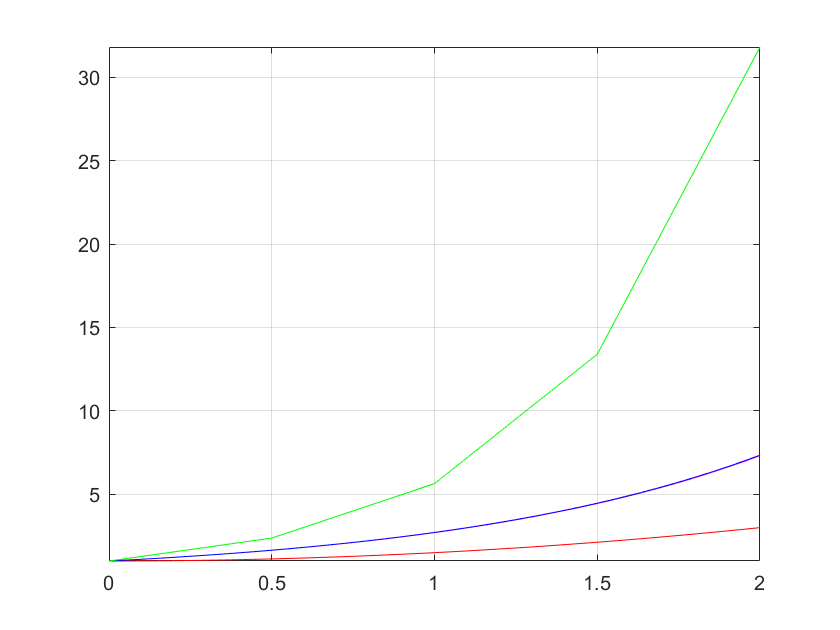

% t en [0,2]

%a)
y=@(t) 1+t.^2/2;
fplot(y,[0 2], 'r')
hold on
grid on
f= @(y,t) t;
[t,y] = odeEuler(f,1,0,2,0.01);
plot(t,y,'magenta')
[t,y] = odeMidpoint(f,1,0,2,0.01);
plot(t,y,'blue')
[t,y] = odeTrapecio(f,1,0,2,0.5);
plot(t,y,'green')
hold off

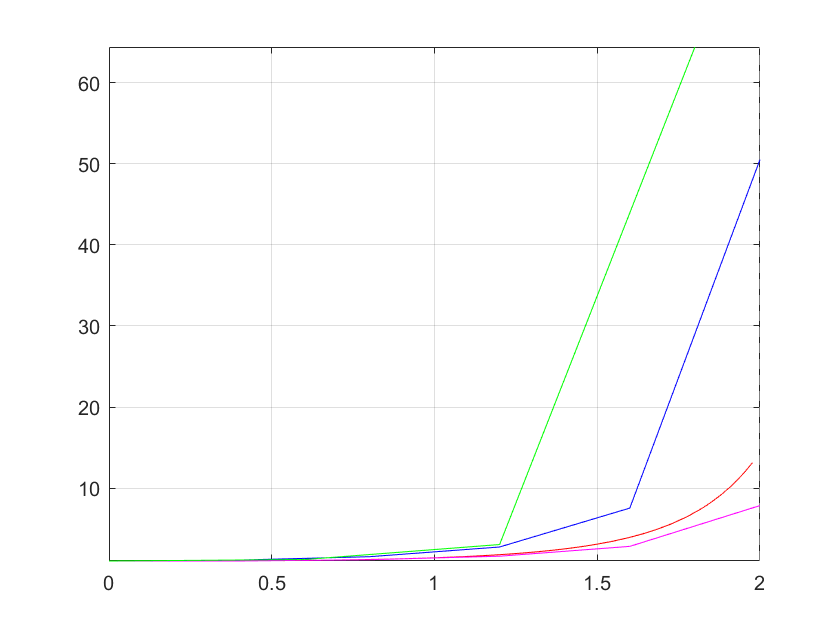

%b)

y=@(t) exp(t.^3/3);
fplot(y,[0 2], 'r')
hold on
grid on
f= @(y,t) (t.^2)*y;
[t,y] = odeEuler(f,1,0,2,0.4);
plot(t,y,'m')
[t,y] = odeMidpoint(f,1,0,2,0.4);
plot(t,y,'b')
[t,y] = odeTrapecio(f,1,0,2,0.6);
plot(t,y,'g')
hold off

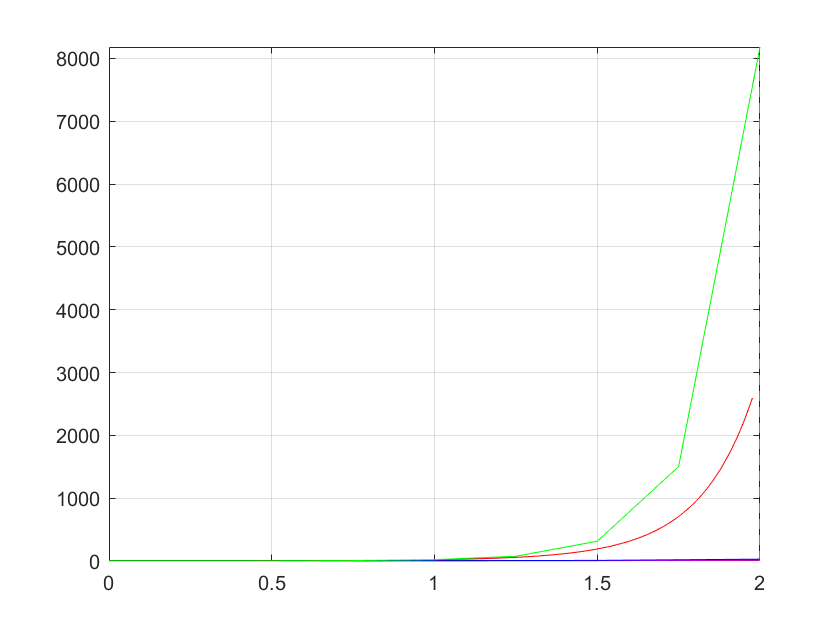

%c)

y=@(t) exp(t.^2+2*t);
fplot(y,[0 2], 'r')
hold on
grid on
f= @(y,t) 2*(t+1)*y;
[t,y] = odeEuler(f,1,0,2,0.5);
plot(t,y,'m')
[t,y] = odeMidpoint(f,1,0,2,0.5);
plot(t,y,'b')
[t,y] = odeTrapecio(f,1,0,2,0.25);
plot(t,y,'g')
hold off


$$y^{\prime } =y\left(1-y\right)$$
      
$$y\left(0\right)=1/2$$


% t en [0,6]
y=@(t) exp(t)/(1+exp(t));
fplot(y,[0 6] , 'r')

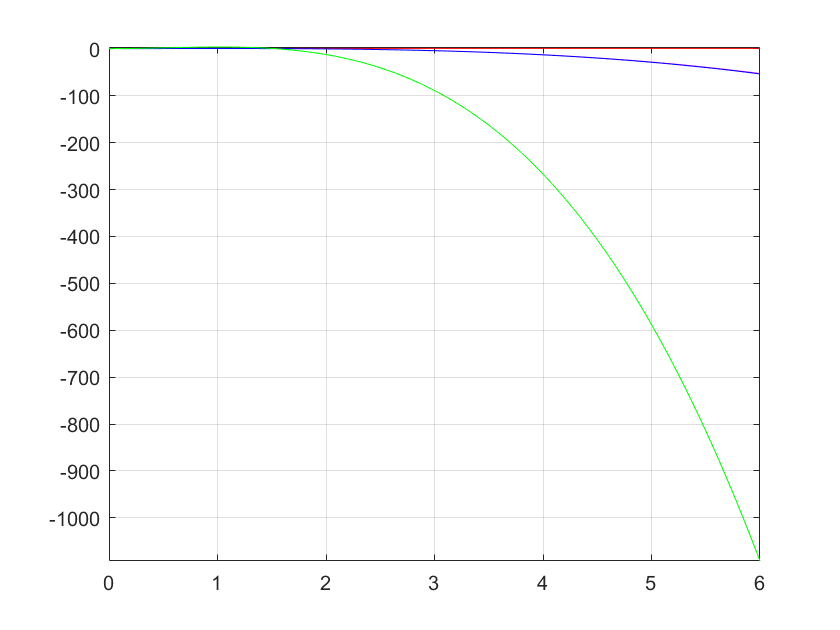

hold on
grid on
f= @(y,t) y*(1-y);
[t,y] = odeEuler(f,0.5,0,6,0.05);
plot(t,y,'m')
[t,y] = odeMidpoint(f,0.5,0,6,0.05);
plot(t,y,'b')
[t,y] = odeTrapecio(f,0.5,0,6,0.05);
plot(t,y,'g')
hold off


$$y^{\prime } =k{\left(a_0 -y\right)}^2 \left(b_0 -y/2\right)$$
     
$$y\left(0\right)=0$$


$k=0\ldotp 00713$; $a_0 =4$; $b_0 =1$

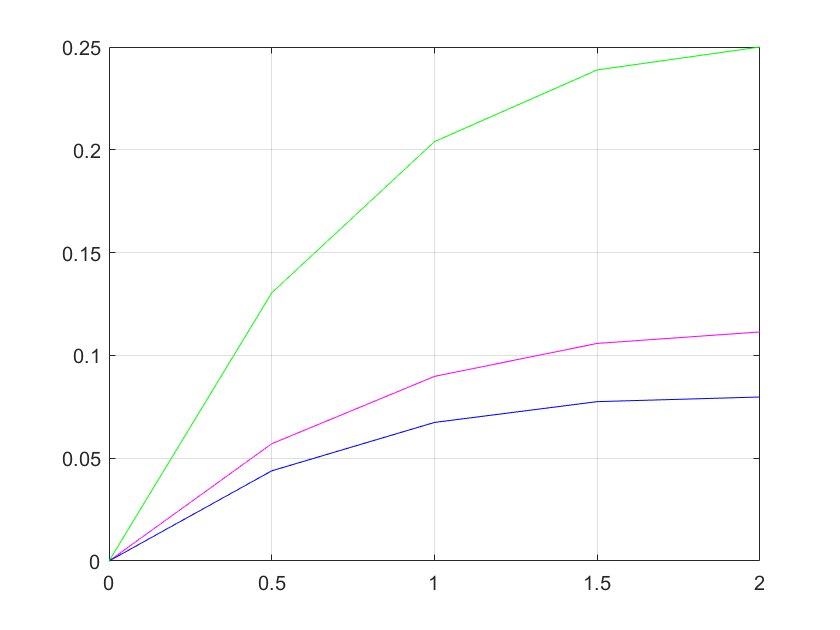

% t en [0,400]
k=0.00713;
a0=4;
b0=1;


f= @(y,t) k*((a0-y).^2)*(b0-y/2);
[t,y] = odeEuler(f,0,0,2,0.5);
plot(t,y,'m')
hold on
grid on
[t,y] = odeMidpoint(f,0,0,2,0.5);
plot(t,y,'b')
[t,y] = odeTrapecio(f,0,0,2,0.5);
plot(t,y,'g')
hold off

Resuelve el siguiente problema de valor inicial en el intervalo de $t=0$ a $t=2$


$$y^{\prime } =yt^2 -1\ldotp 1y$$
      
$$y\left(0\right)=1$$


% Solucion analitica
syms y(t) 
eqn = diff(y,t) == y*t^2 - 1.1*y;
yG = dsolve(eqn)

$$yG = C_{1}\,{\mathrm{e}}^{\frac{t\,\left(10\,t^{2}-33\right)}{30}}$$

cond = y(0) == 1;
yP = dsolve(eqn,cond)

$$yP = {\mathrm{e}}^{\frac{t\,\left(10\,t^{2}-33\right)}{30}}$$

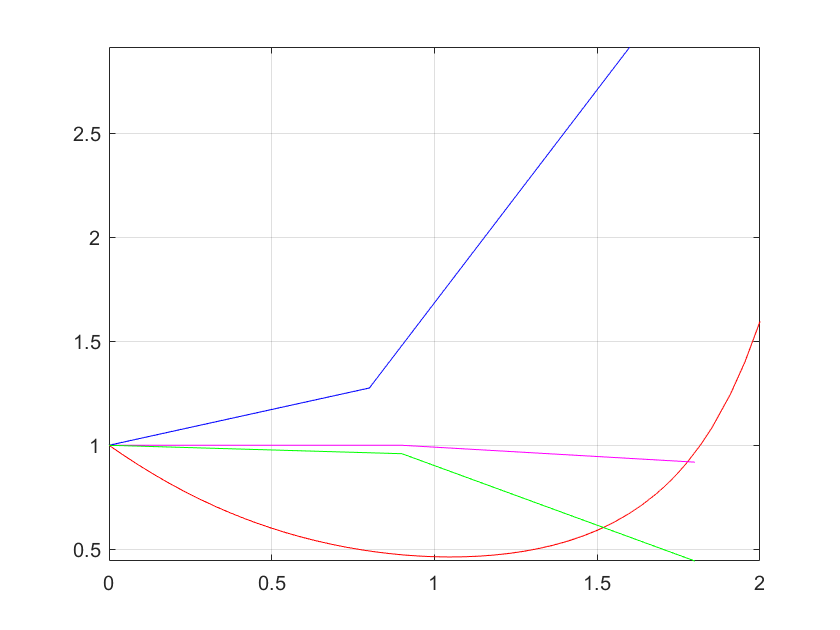

fplot(yP, [0 2],'r');
hold on
grid on

f= @(y,t) y*t.^2 -1.1*y;
[t,y] = odeEuler(f,1,0,2,0.9);
plot(t,y,'m')
[t,y] = odeMidpoint(f,1,0,2,0.8);
plot(t,y,'b')
[t,y] = odeTrapecio(f,1,0,2,0.9);
plot(t,y,'g')

hold off;

Si se drena el agua desde un tanque cilindrico vertical abriendo una válvula en la base, el líquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$y^{\prime } =-k\sqrt{y}$           (*y* en metros y *t* en minutos)

donde *k* es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero.

¿En cuántos minutos se vaciará un tanque que inicialmente tiene 3 metros de agua?

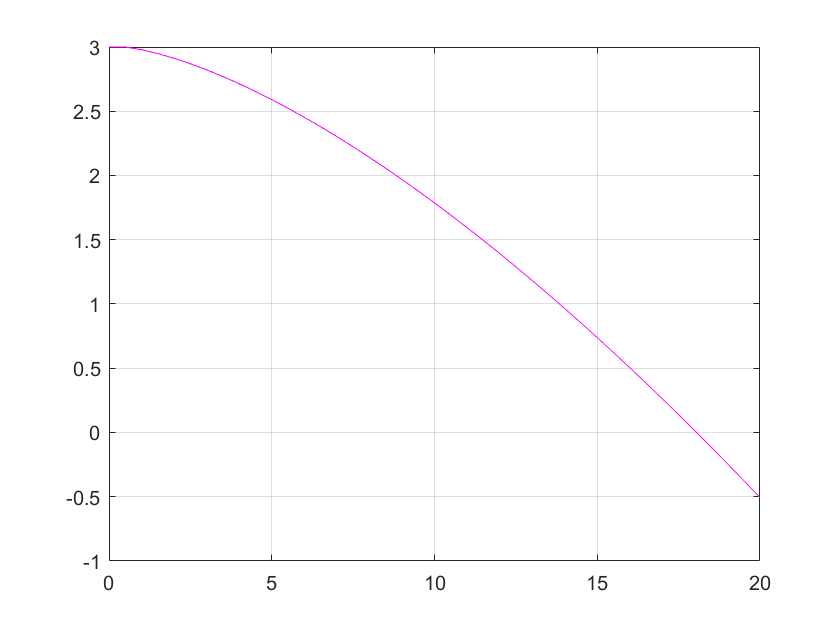

%
k=0.06;
f= @(y,t) -k*sqrt(y);
[t,y] = odeEuler(f,3,0,20,0.5);
%Aproximadamente en el segundo 18
plot(t,y,'m')
grid on

Para simular la dinámica de una poblacion se utiliza el modelo logistico:


$$p^{\prime } =k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde *p *es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y$p_{\max }$es la capacidad de carga. Simula la población mundial entre 1950 y 2022, sabiendo que en 1950 había 2555 millones de personas. Para la simulación utiliza los siguientes valores de parametros: $k_{\textrm{gm}} =0\ldotp 026/\textrm{año}$ y $p_{\max } =12000$ millones de personas-

¿Cuántos millones de personas habrá en 2022?

%
k=0.026;
pM=12000;
f= @(y,t) k*(1-y/pM)*y;
[t,y] = odeEuler(f,2555,1955,2022,0.5);
%Aproximadamente en el segundo 18
poblacion2022=max(y)

poblacion2022 = 5.4446e+03

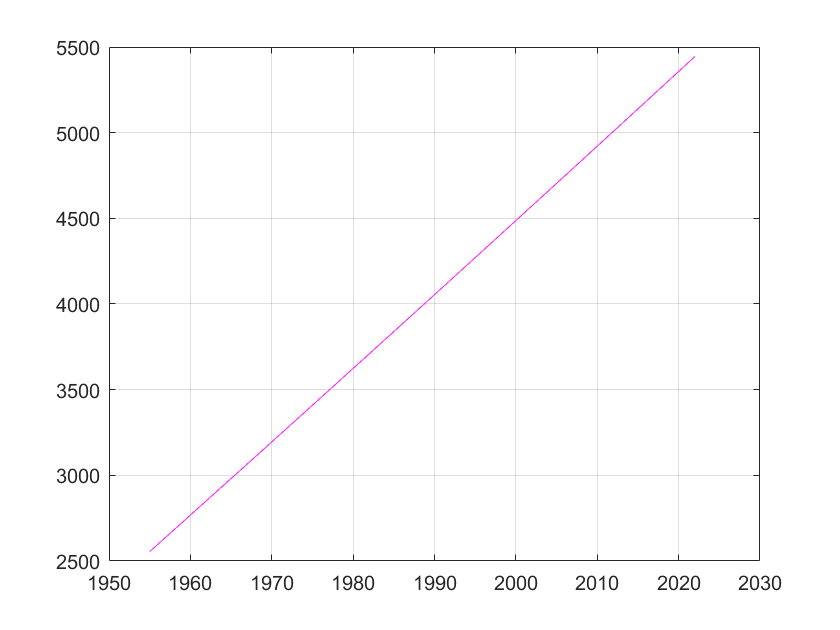

plot(t,y,'m')
grid on

More examples

% y(0) = 1; 0 <=t<= 10;
% f         Exact solution
% 0         1
% t         1+t^2/2
% y         exp(t)
% -y        exp(-t)
% 2*y-y^2   2/(1+exp(-2*t))


function [t,y] = odeEuler(f,y0,t0,tf,h)
    t = t0:h:tf; %crea el vector de las ts que inicia en t0, aumenta de h en h y termina en tf
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    y(1) = y0; % valor inicial de y
    for i=1:1:n-1
        phi = f(t(i),y(i));
        y(i+1) = y(i) + phi*h;
    end
end

function [t,y] = odeMidpoint(f,y0,t0,tf,h)
    t = t0:h:tf; %crea el vector de las ts que inicia en t0, aumenta de h en h y termina en tf
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    y(1) = y0; % valor inicial de y
    aux=h/2;
    
    for i=1:1:n-1    
        phi = f(t(i)+aux,y(i)+aux);
        y(i+1) = y(i) + phi*h;
    end
end

function [t,y] = odeTrapecio(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    y = zeros(1,n);
    y(1) = y0; % valor inicial de y
    
    for i=1:1:n-1
        phi = f(t(i),y(i));
        predictor = y(i) + phi*h;
        y(i+1) = y(i) + phi+((f(t(i+1),predictor))/2)*h;
    end

end